# E11-bis

#### Local Features

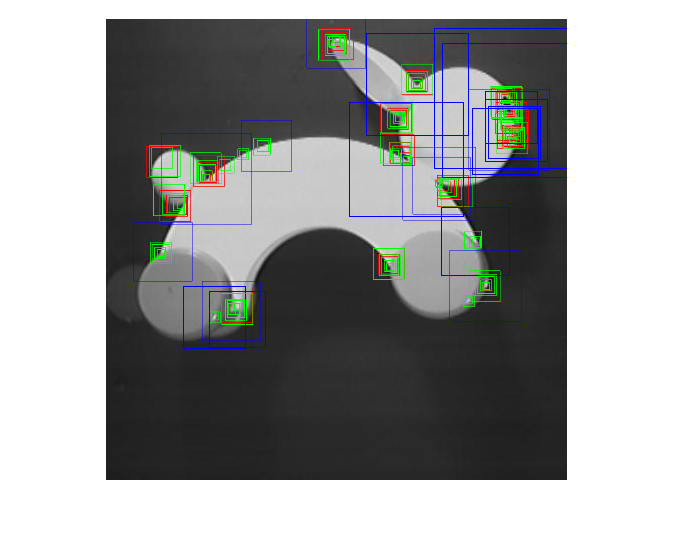

im = imread('rabbit.jpg');
imshow(im)
sizes = [7, 11, 17, 21,31];
hold on

for j = 1:size(sizes, 2)
    kp = detectHarrisFeatures(im, 'FilterSize', sizes(j), 'MinQuality',0.1);
    wsize = sizes(j);
    for i = 1:size(kp,1)
        rectangle('Position', [kp.Location(i,1) - wsize/2, kp.Location(i,2) - wsize/2, wsize, wsize], 'EdgeColor', 'r');
    end
end
for j = 1:size(sizes, 2)
    kp = detectMinEigenFeatures(im, 'FilterSize', sizes(j), 'MinQuality',0.12);
    wsize = sizes(j);
    for i = 1:size(kp,1)
        rectangle('Position', [kp.Location(i,1) - wsize/2, kp.Location(i,2) - wsize/2, wsize, wsize], 'EdgeColor', 'g');
    end
end
kp = detectFASTFeatures(im, 'MinQuality',0.1);
for i = 1:size(kp,1)
    wsize = kp.Metric(i);
    rectangle('Position', [kp.Location(i,1) - wsize/2, kp.Location(i,2) - wsize/2, wsize, wsize], 'EdgeColor', 'b');
end
hold off

DoG

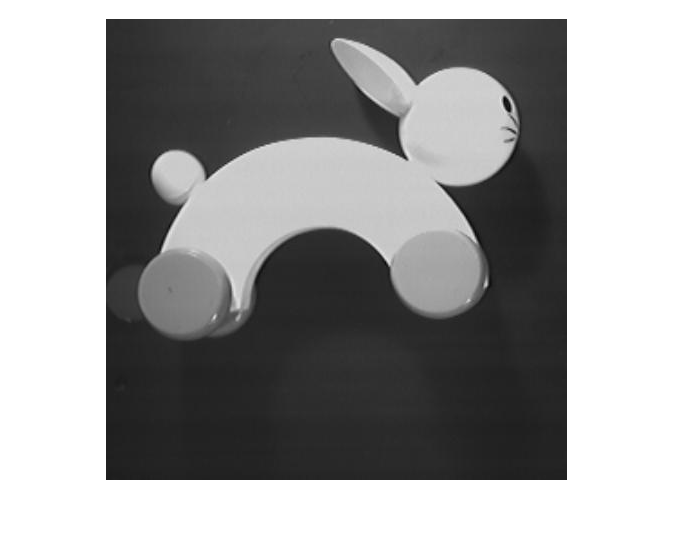

im = imread('rabbit.jpg');
imshow(im)

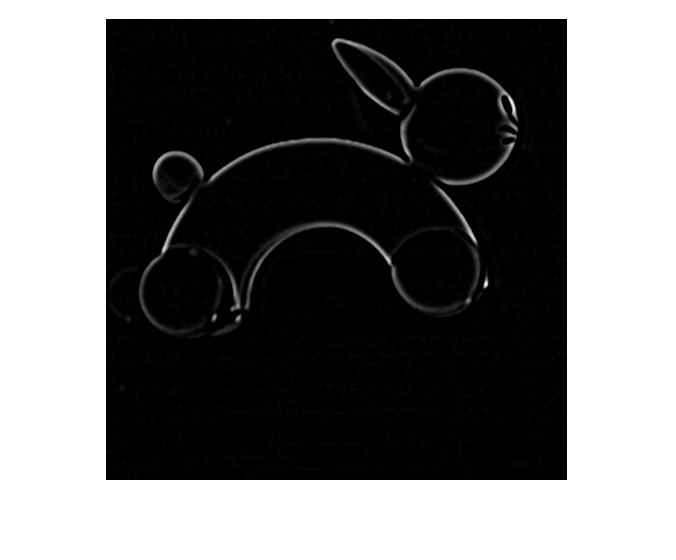

h = fspecial("gaussian", 7, 7/4);
G(:,:,1) = imfilter(im, h, 'replicate');

h = fspecial("gaussian", 15, 15/4);
G(:,:,2) = imfilter(im, h, 'replicate');

h = fspecial("gaussian", 30, 30/4);
G(:,:,3) = imfilter(im, h, 'replicate');

imshow(G(:,:,1) - G(:,:,2), [])

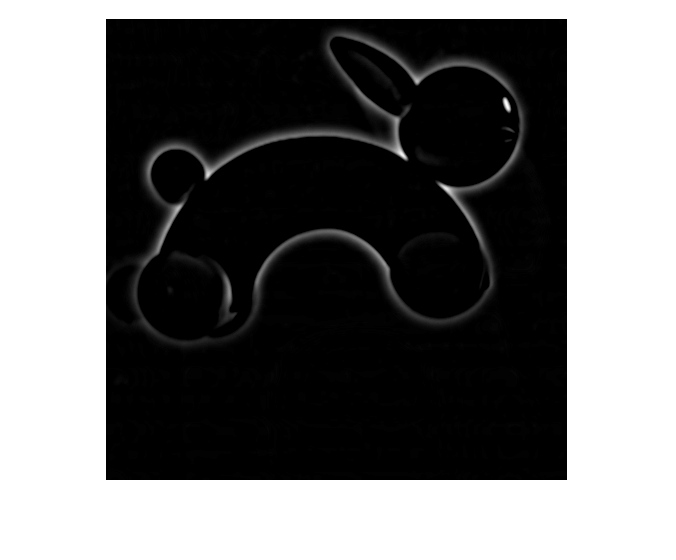

imshow(G(:,:,3) - G(:,:,1), []) % detecció de contorns: Gaussiana -> suavitza els contorns

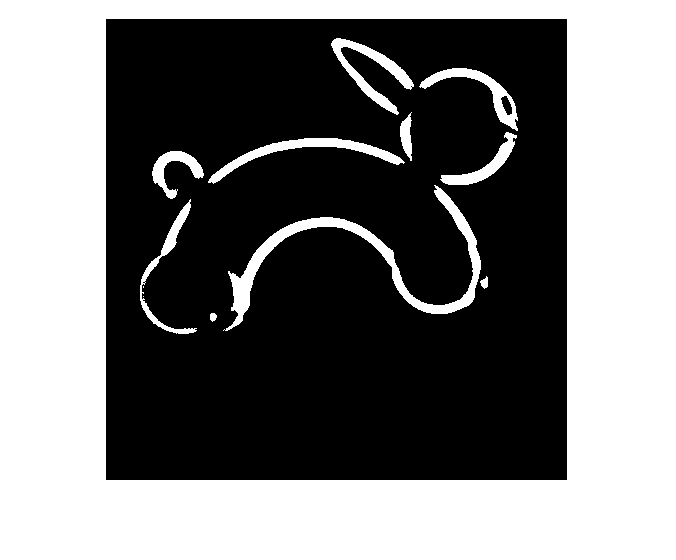

DoG(:,:,1) = abs(G(:,:,1) - G(:,:,2));
DoG(:,:,2) = abs(G(:,:,2) - G(:,:,3));

[V, S] = max(DoG, [], 3);
I = V > 10;
imshow(I);

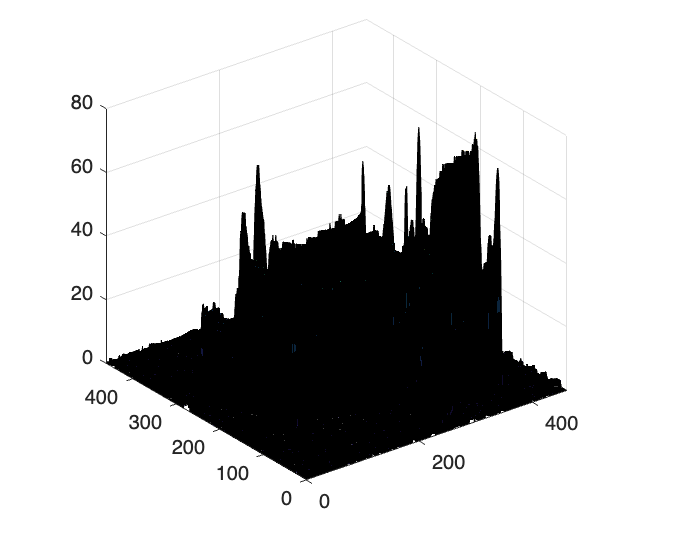

surf(double(V).*double(S))

SIFT & matching

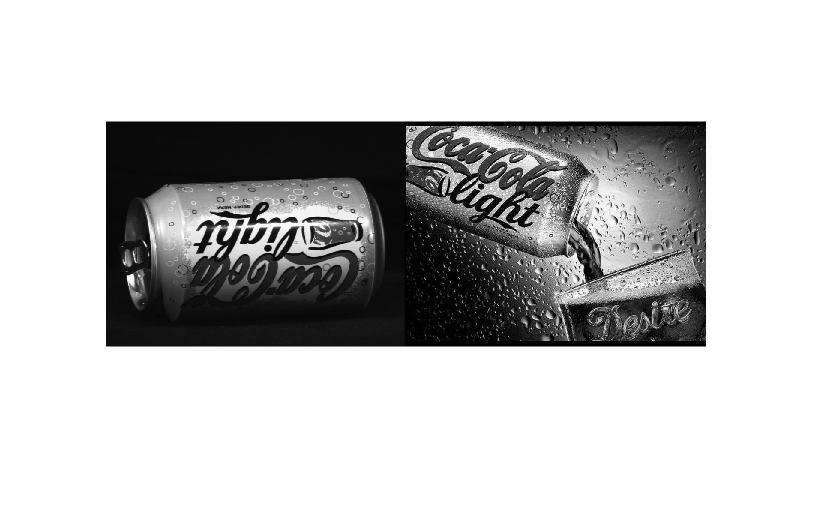

im_obj = rgb2gray(imread('coke.jpg'));
im_esc = rgb2gray(imread('anunci.jpg'));
montage({im_obj, im_esc});

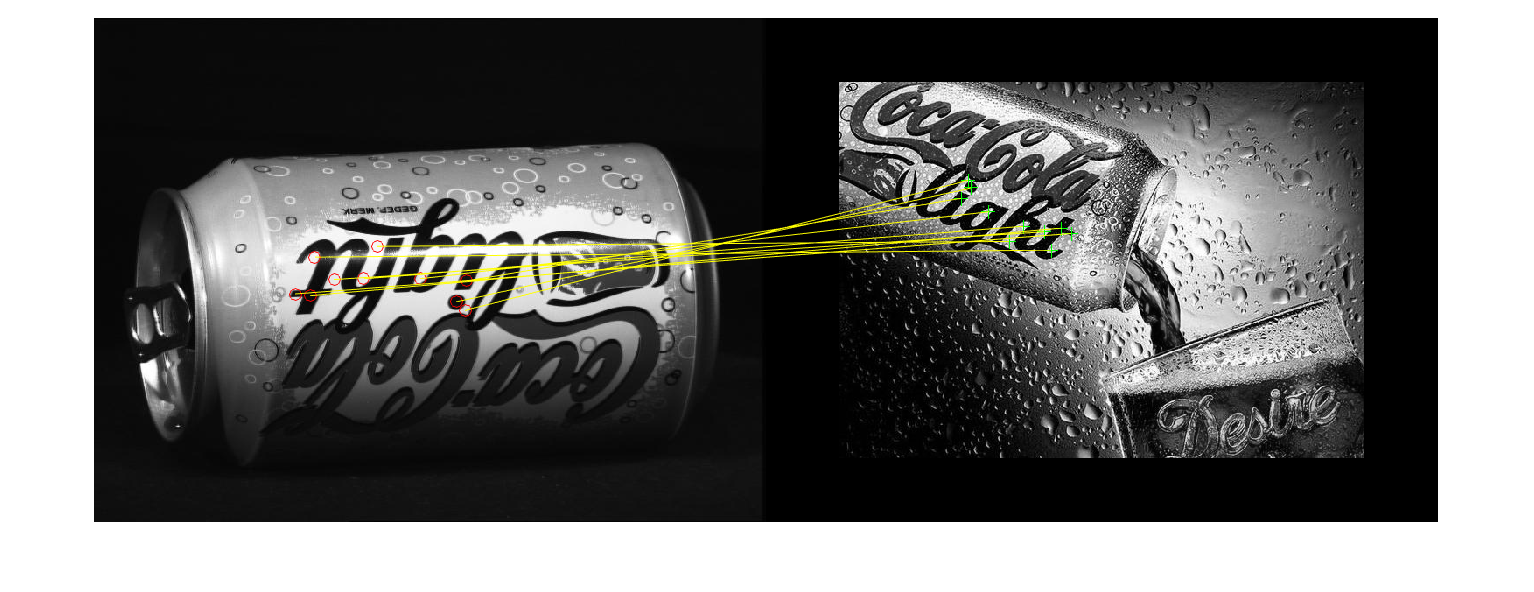

kp_obj = detectSIFTFeatures(im_obj);
kp_obj = selectStrongest(kp_obj, 50);
%imshow(im_obj);
%hold on
%plot(kp_obj);
%hold off
kp_esc = detectSIFTFeatures(im_esc);
kp_esc = selectStrongest(kp_esc, 200);
%imshow(im_esc)
%hold on
%plot(kp_esc);
%hold off
[feat_obj, kp_obj] = extractFeatures(im_obj, kp_obj, "Method", "SIFT");
[feat_esc, kp_esc] = extractFeatures(im_esc, kp_esc, "Method", "SIFT");

pairs = matchFeatures(feat_obj, feat_esc, 'MatchThreshold', 20);

m_kp_obj = kp_obj(pairs(:,1),:);
m_kp_esc = kp_esc(pairs(:,2),:);

figure
showMatchedFeatures(im_obj, im_esc, m_kp_obj, m_kp_esc, "montage")

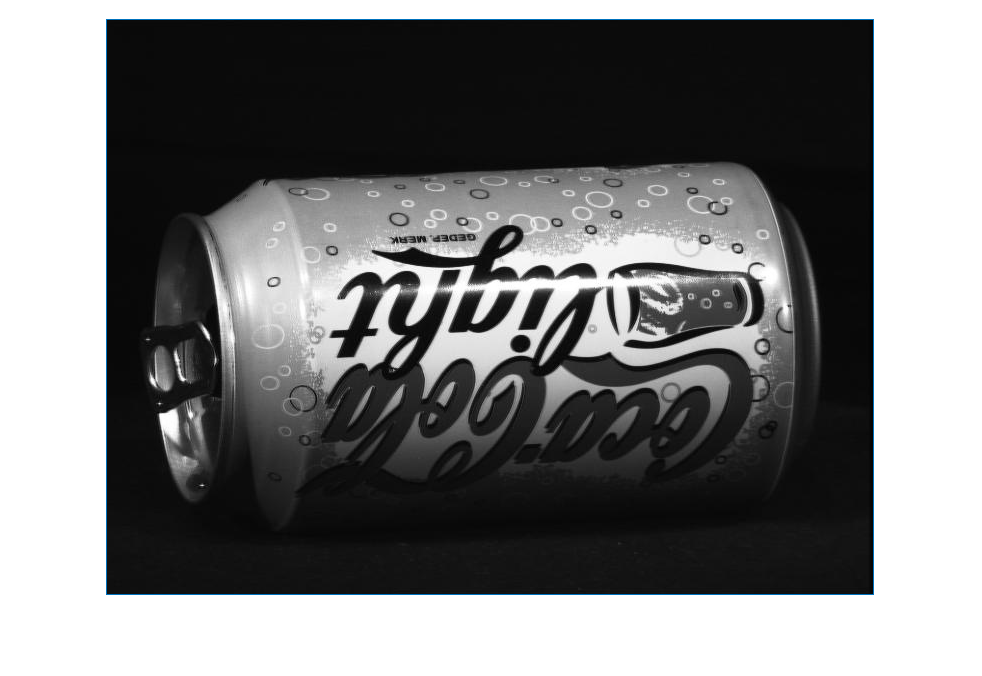

T = estimateGeometricTransform(m_kp_obj, m_kp_esc, "affine");
[f, c] = size(im_obj);
figure
imshow(im_obj);
box = [1,1; 1,f; c,f; c,1; 1,1];
hold on
line(box(:,1), box(:,2));
nbox = transformPointsForward(T, box);
hold off

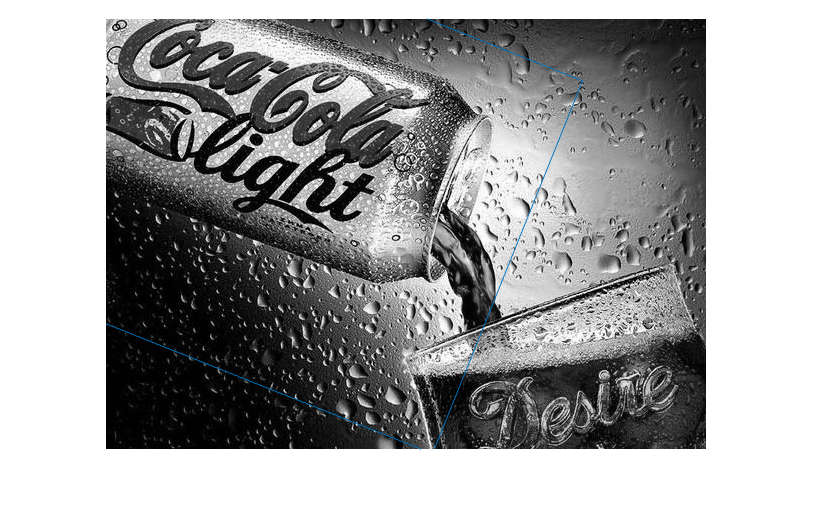

figure 
imshow(im_esc);
hold on
line(nbox(:,1), nbox(:,2));
hold off